clc;
clear;
total = 0;
record = []


record =

     []



## Initialization

modOrder = 4;  % for 4-QAM
bitsPerSymbol = log2(modOrder)  % modOrder = 2^bitsPerSymbol

bitsPerSymbol = 2


maxValue = 0.8;
minValue = -maxValue;
multi_path_num = 7;
randomNumbers_real = minValue + (maxValue - minValue) * rand(1, multi_path_num);
randomNumbers_imag = minValue + (maxValue - minValue) * rand(1, multi_path_num);

mpChan = [randomNumbers_real'+i.*randomNumbers_imag']  % multipath channel

mpChan =   -0.1302 - 0.1713i
   0.2214 + 0.0927i
  -0.6797 - 0.6430i
  -0.7896 - 0.5797i
  -0.4914 + 0.6931i
  -0.2440 + 0.2585i
   0.5350 - 0.6853i



SNR = 25   % dB, signal-to-noise ratio of AWGN

SNR = 25


numCarr = 1024;  % number of subcarriers
cycPrefLen = 32;  % cyclic prefix length

## Set the Guard Band

GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =          961         962         963         964         965         966         967         968         969         970         971         972         973         974         975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 513


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


## Set the pilot

pilot_len = 16;

left_polit = left_gb(end)+1 :  left_gb(end)+ pilot_len

left_polit =     65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80


right_polit = numCarr - 2*GB_len - pilot_len : numCarr - 2*GB_len -1

right_polit =    880   881   882   883   884   885   886   887   888   889   890   891   892   893   894   895


pilot_loc = [left_polit, right_polit]'

pilot_loc =     65
    66
    67
    68
    69
    70
    71
    72
    73
    74



%generate pilot
my_pilot = dec2bin(2^(pilot_len*bitsPerSymbol -1) + pilot_len*multi_path_num -1)

my_pilot = '10000000000000000000000001101111'

pilot = split(my_pilot,'')

pilot = 34×1 cell 数组
    {0×0 char}
    {'1'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'0'     }
    {'1'     }
    {'1'     }
    {'0'     }
    {'1'     }


pilot = str2double(pilot(2:end-1))

pilot =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


pilot = [pilot;pilot]

pilot =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0



%set pilot location
intervial = round((numCarr - length(nullIdx))/(2*pilot_len))

intervial = 28

pilot_place = 1:intervial:1+intervial*(2*pilot_len-2)

pilot_place =      1    29    57    85   113   141   169   197   225   253   281   309   337   365   393   421   449   477   505   533   561   589   617   645   673   701   729   757   785   813   841


pilot_place = [pilot_place';numCarr - length(nullIdx)]

pilot_place =      1
    29
    57
    85
   113
   141
   169
   197
   225
   253


sc_pilot_place = pilot_place

sc_pilot_place =      1
    29
    57
    85
   113
   141
   169
   197
   225
   253



%set pilot bits location
pilot_place = sort([bitsPerSymbol.*pilot_place;bitsPerSymbol.*pilot_place-1])

pilot_place =      1
     2
    57
    58
   113
   114
   169
   170
   225
   226


bit_place = (1:(numCarr - length(nullIdx))*bitsPerSymbol)'

bit_place =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


bit_place(pilot_place) = []

bit_place =      3
     4
     5
     6
     7
     8
     9
    10
    11
    12


%class(pilot)

## Generate random data & integrate pilot

numDataCarr = numCarr - length(nullIdx)

numDataCarr = 895

numBits = numDataCarr*bitsPerSymbol

numBits = 1790

dataBits = zeros(numBits,1)

dataBits =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


dataBits(bit_place) = randi([0,1],length(bit_place),1);
pure_databit = dataBits

pure_databit =      0
     0
     1
     1
     1
     0
     1
     0
     0
     0


pure_databit(pilot_place) = []

pure_databit =      1
     1
     1
     0
     1
     0
     0
     0
     0
     0


dataBits(pilot_place) = pilot

dataBits =      1
     0
     1
     1
     1
     0
     1
     0
     0
     0


%class(puredataBits)

4-QAM modulation

qamModOut = qammod(dataBits,modOrder,"InputType","bit","UnitAveragePower",true)

qamModOut =    0.7071 + 0.7071i
   0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i


OFDM transform for the 4-QAM signal

ofdmModOut = ofdmmod(qamModOut,numCarr,cycPrefLen,nullIdx)

ofdmModOut =    0.0085 - 0.0402i
   0.0109 - 0.0157i
  -0.0108 - 0.0069i
  -0.0307 + 0.0212i
   0.0014 + 0.0123i
   0.0274 - 0.0101i
  -0.0002 + 0.0115i
   0.0039 - 0.0097i
  -0.0004 - 0.0102i
  -0.0207 + 0.0272i


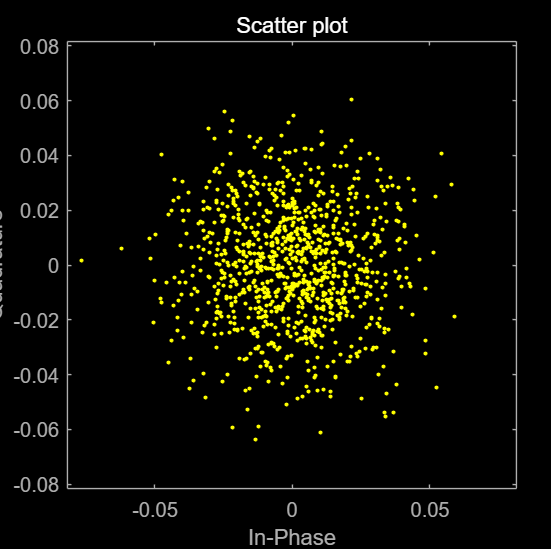

scatterplot(ofdmModOut)


mpChanOut = filter(mpChan,1,ofdmModOut); %apply mutipath
chanOut = mpChanOut

chanOut =   -0.0080 + 0.0038i
   0.0015 - 0.0079i
  -0.0276 + 0.0222i
  -0.0417 + 0.0305i
   0.0020 + 0.0434i
   0.0467 + 0.0438i
   0.0409 - 0.0341i
  -0.0225 - 0.0667i
  -0.0376 - 0.0304i
  -0.0057 + 0.0465i


chanOut = awgn(mpChanOut,SNR,"measured"); %apply AWGN

OFDM demodulation

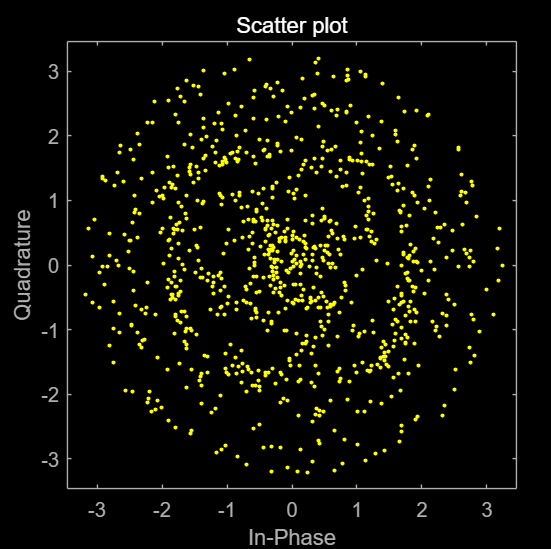

ofdmDemodOut = ofdmdemod(chanOut,numCarr,cycPrefLen,cycPrefLen,nullIdx);
scatterplot(ofdmDemodOut)

channel estimate

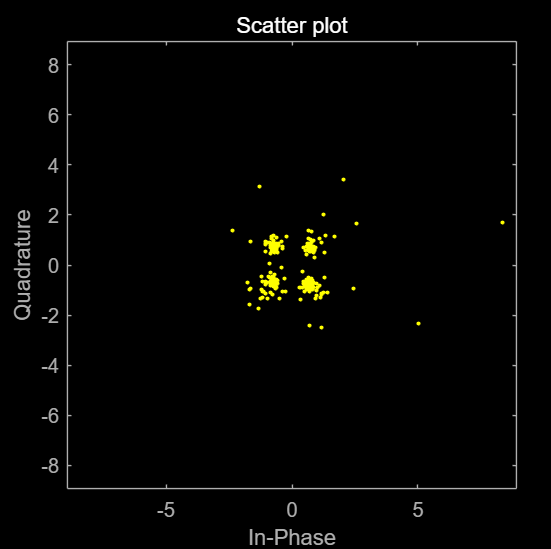

receivedPilot = ofdmDemodOut(sc_pilot_place);
sentpoilt = qamModOut(sc_pilot_place);
estimatedChannelResponse = receivedPilot ./ sentpoilt;
% % test pilot
% test = receivedPilot ./ estimatedChannelResponse
% test_pilot = qamdemod(test,modOrder,"OutputType","bit","UnitAveragePower",true)
% testErrors = nnz(pilot~=test_pilot)

% LS
carrIdx = 1:numCarr-length(nullIdx);
% carrIdx(nullIdx) = [];
% carrIdx(sc_pilot_place) = []
% ofdmDemodOut(sc_pilot_place) = []

% 'linear' for Linear interpolation
fullChannelEstimate = (interp1(sc_pilot_place, estimatedChannelResponse, carrIdx, 'spline'))';
%transverse is used, so the conjugate is needed to turn it back
fullChannelEstimate = conj(fullChannelEstimate);
%fullChannelEstimate(nullIdx) = [];
equalizedSignal = ofdmDemodOut ./ fullChannelEstimate;
scatterplot(equalizedSignal)

[fullChannelEstimate(sc_pilot_place), estimatedChannelResponse]

ans =   -0.9187 - 0.3062i  -0.9187 - 0.3062i
  -0.5508 + 0.1582i  -0.5508 + 0.1582i
  -0.0213 + 0.0567i  -0.0213 + 0.0567i
  -0.1038 - 0.5248i  -0.1038 - 0.5248i
  -1.0235 - 1.0473i  -1.0235 - 1.0473i
  -2.0976 - 0.3700i  -2.0976 - 0.3700i
  -2.2750 + 1.3396i  -2.2750 + 1.3396i
  -1.2559 + 2.7887i  -1.2559 + 2.7887i
   0.8814 + 3.0081i   0.8814 + 3.0081i
   2.6195 + 1.8288i   2.6195 + 1.8288i



qamDemodOut = qamdemod(equalizedSignal,modOrder,"OutputType","bit","UnitAveragePower",true);
numBitErrors = nnz(dataBits~=qamDemodOut)

numBitErrors = 7

BER = numBitErrors/length(pure_databit)

BER = 0.0041

piloterror = nnz(pilot ~= qamDemodOut(pilot_place))

piloterror = 0

total = total + BER

total = 0.0041

record = [record;BER]

record = 0.0041

test with origin multipath maxtrix

% mpChanFreq = fftshift(fft(mpChan,numCarr))
% mpChanFreq(nullIdx) = []


equalization

% eqOut = ofdmDemodOut ./ mpChanFreq
% scatterplot(equalizedSignal)

% qamDemodOut = qamdemod(equalizedSignal,modOrder,"OutputType","bit","UnitAveragePower",true)
% numBitErrors = nnz(dataBits~=qamDemodOut)
% BER = numBitErrors/numBits

% specAn = dsp.SpectrumAnalyzer("NumInputPorts",2, ...
%     "SpectralAverages",50,...
%     "ShowLegend",true);
% specAn(ofdmModOut,chanOut)